% Define the data for lower limit, upper limit, and frequency
lowerLimits = [1,2,3,4,5,6,7,8,9,10,11,12,13,14]; 
upperLimits = [2,3,4,5,6,7,8,9,10,11,12,13,14,15]; 
frequencies = [10,18,26,45,56,73,58,93,87,121,143,162,156,123];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         1             2            10   
         2             3            18   
         3             4            26   
         4             5            45   
         5             6            56   
         6             7            73   
         7             8            58   
         8             9            93   
         9            10            87   
        10            11           121   
        11            12           143   
        12            13           162   
        13            14           156   
        14            15           123   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 10.26


fprintf('Median: %.2f\n', medianValue);

Median: 10.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 12.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 3.27


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 10.97


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 1.53


fprintf('Karl: %.2f\n', Karl);

Karl: -0.68


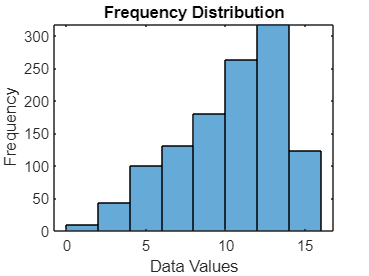


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');